# Laboratorium 3

#### Janusz Pawlicki

## 1 Wstęp

### 1.1 Cel Laboratorium

Zapoznanie się z charakterystykami czasowymi (odpowiedziami obiektu na określone wymuszenie w dziedzinie czasu) oraz częstotliwościowymi (odpowiedziami obiektu na wymuszenie sinusoidalne) podstawowych obiektów dynamicznych.

Ćwiczenie ma być wykonane drogą symulacji w środowisku MATLAB. Należy zbadać odpowiedzi obiektów takich jak:

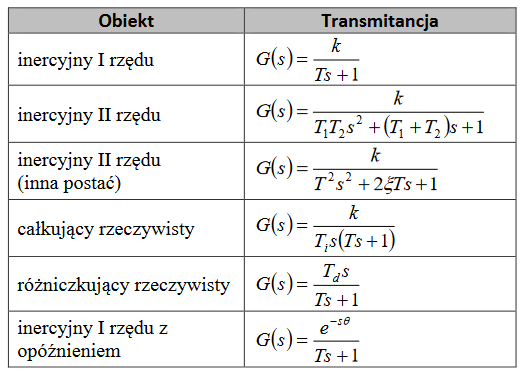

Dla obiektu (charakterystyka czsowa)

Na wymuszenie sinusoidalne postaci *A* sin(wt) (charakterystyka częstotliwościowa)

### 1.2 Transmitancja operatorowa

Transmitancja operatorowa (funkcja przejścia) to stosunek transformaty Laplace'a sygnału wyjściowego Y(s) do transformaty Laplace'a sygnału wejściowego U(s) przy zerowych warunkach początkowych:

Transmitancja w postaci wielomianowej jest dana wzorem:

W Matlabie transmitancja jest reprezentowana przez dwa wektory, zawierające współczynniki jej licznika i mianownika (w kolejności od najwyższej potęgi „s”). Sposób zapisu powyższych obiektów jest podany w tabeli:

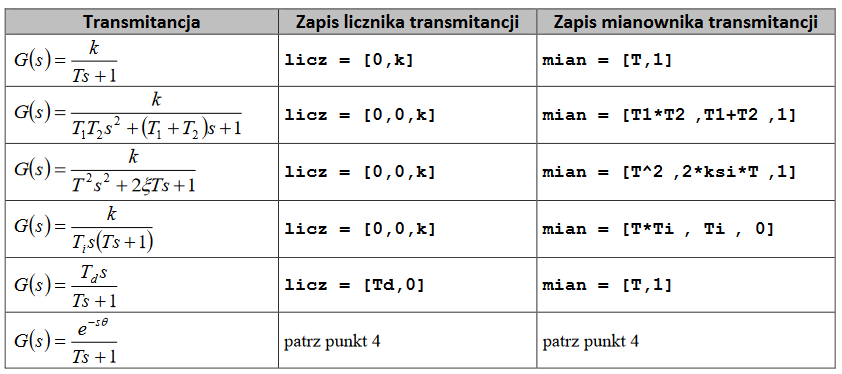

### 1.3 Obiekt inercyjny I rzędu z opóźnieniem

W systemach dynamicznych często możemy się spotkać z pojęciem czasu opóźnienia. Przykładem może być zjawisko przepływu cieczy przez rurociąg. Zakładamy, że przepływ jest tłokowy i czas przepływu pojedynczej cząstki cieczy wzdłuż całego rurociągu równy jest theta. W tym przypadku odcinek rurociągu można traktować jako element opóźniający

Jeżeli przyjmiemy, że zachowanie się pewnej zmiennej u wlotu do rurociągu określa funkcja f(t) (reprezentująca np. temperaturę lub skład cieczy) to po czasie theta na końcu rurociągu zaobserwujemy identyczny przebieg tej zmiennej.

Transformata Laplace’a funkcji przesuniętej w czasie o theta jednostek czasu wynosi:

Wynika stąd, że zależność zmiennej wyjściowej od zmiennej wejściowej dla układu opóźniającego

wyraża się transmitancją **e^-s * theta.**

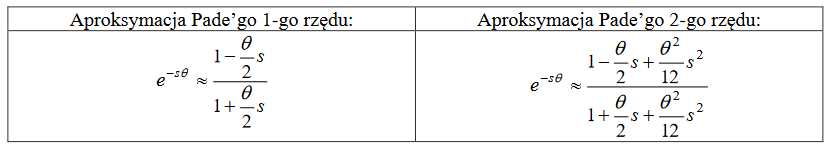

Aproksymacja Pade’go jest zaimplementowana w Matlabie w funkcji `pade`. W celu zamodelowania obiektu inercyjnego I rzędu z opóźnieniem w Matlabie należy wykonać poniższe czynności:

a) Wyznaczamy transmitancję członu opóźniającego przy pomocy funkcji PADE:

`[licz_op,` `mian_op]` `=` `pad``e(theta,` `n)`

gdzie: theta – opóźnienie w [s], n – rząd aproksymacji (np. n = 5). Po wykonaniu tej instrukcji

otrzymujemy licznik i mianownik transmitancji członu opóźniającego zapisany pod zmiennymi

licz_op i mian_op.

b) Zapisujemy transmitancję obiektu inercyjnego bez opóźnienia:

`licz_iner` `=` `[0,k];` `mian_iner` `=` `[T,1];`

c) Łączymy obie transmitancje szeregowo za pomocą instrukcji SERIES:

`[licz,` `mian]` `=` `series(licz_op,` `mian_op,` `licz_iner,` `mian_iner);`

Otrzymujemy w ten sposób licznik i mianownik transmitancji obiektu inercyjnego z opóźnieniem.

## 2 Przebieg laboratorium

### 2.1 Charaktrystyka czasowa dla podanych obiektów z wymuszeniem:

### 2.1 A) Inercyjny I rzędu

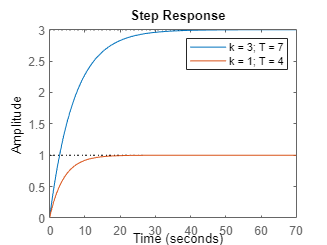

k = 3;
T = 7;
k1 = 1;
T1 = 4;

licz = [0, k];
mian = [T, 1];
licz1 = [0, k1];
mian1 = [T1, 1];

step(licz, mian) % charakterystyka skokowa

hold on 

step(licz1, mian1)

legend('k = 3; T = 7', 'k = 1; T = 4')

hold off

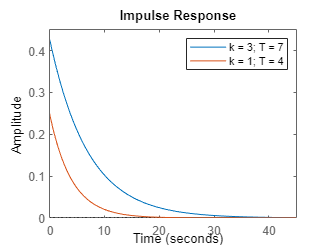


impulse(licz, mian) % charakterystyka impulsowa

hold on

impulse(licz1, mian1)

legend('k = 3; T = 7', 'k = 1; T = 4')

hold off

### 2.1 B) Inercyjny II rzędu

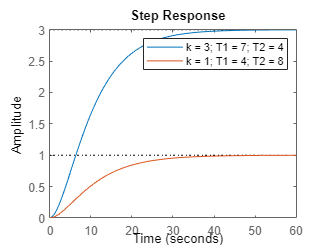

k = 3;
T1 = 7;
T2 = 4;
k1 = 1;
T11 = 4;
T21 = 8;

licz = [0, 0, k];
mian = [T1 * T2, T1 + T2, 1];
licz1 = [0, 0, k1];
mian1 = [T11 * T21, T11 + T21, 1];

step(licz, mian)

hold on 

step(licz1, mian1)

legend('k = 3; T1 = 7; T2 = 4', 'k = 1; T1 = 4; T2 = 8')

hold off

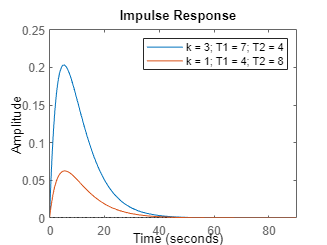


impulse(licz, mian)

hold on

impulse(licz1, mian1)

legend('k = 3; T1 = 7; T2 = 4', 'k = 1; T1 = 4; T2 = 8')

hold off

### 2.1 C) Inercyjny II rzędu (inna postać)

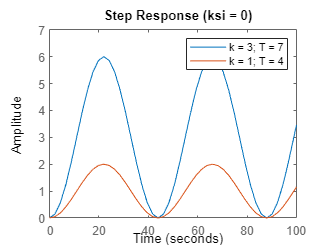

k = 3;
T = 7;
ksi0 = 0;
ksi1 = 0.7;
ksi2 = 1;
ksi3 = 1.3;
k1 = 1;
T1 = 4;

%Układ oscylacyjny nietłumiony

licz = [0, 0, k];
mian = [T^2 ,2*ksi0*T ,1];

licz1 = [0, 0, k1];
mian1 = [T^2 ,2*ksi0*T1 ,1];

step(licz, mian)

hold on 

step(licz1, mian1)

legend('k = 3; T = 7', 'k = 1; T = 4')

axis([0 100 0 7])

title('Step Response (ksi = 0)')

hold off

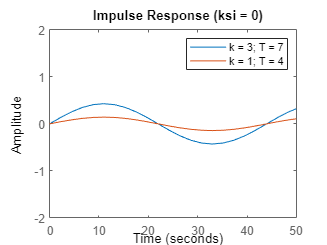


impulse(licz, mian)

hold on

impulse(licz1, mian1)

legend('k = 3; T = 7', 'k = 1; T = 4')

axis([0 50 -2 2])

title('Impulse Response (ksi = 0)')

hold off

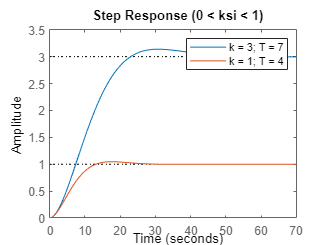


% Układ oscylacyjny tłumiony

licz2 = [0, 0, k];
mian2 = [T^2 ,2*ksi1*T ,1];

licz3 = [0, 0, k1];
mian3 = [T1^2 ,2*ksi1*T1 ,1];

step(licz2, mian2)

hold on 

step(licz3, mian3)

legend('k = 3; T = 7', 'k = 1; T = 4')

title('Step Response (0 < ksi < 1)')

hold off

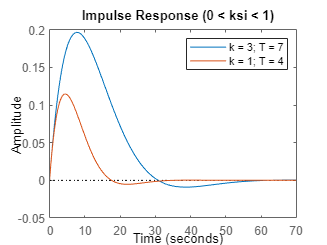


impulse(licz2, mian2)

hold on

impulse(licz3, mian3)

legend('k = 3; T = 7', 'k = 1; T = 4')

title('Impulse Response (0 < ksi < 1)')

hold off

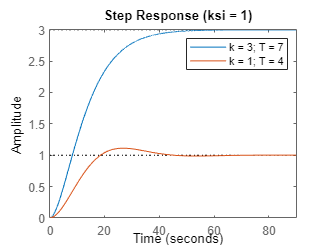


 % Układ aperiodyczny krytyczny 

licz4 = [0, 0, k];
mian4 = [T^2 ,2*ksi2*T ,1];

licz5 = [0, 0, k1];
mian5 = [T^2 ,2*ksi2*T1 ,1];

step(licz4, mian4)

hold on 

step(licz5, mian5)

legend('k = 3; T = 7', 'k = 1; T = 4')

title('Step Response (ksi = 1)')

hold off

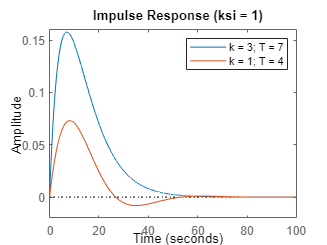


impulse(licz4, mian4)

hold on

impulse(licz5, mian5)

legend('k = 3; T = 7', 'k = 1; T = 4')

title('Impulse Response (ksi = 1)')

hold off

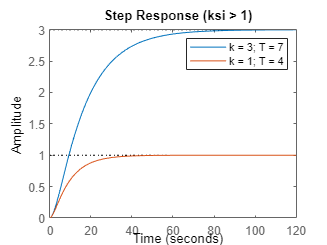


% Układ aperiodyczny

licz6 = [0, 0, k];
mian6 = [T^2 ,2*ksi3*T ,1];

licz7 = [0, 0, k1];
mian7 = [T1^2 ,2*ksi3*T1 ,1];

step(licz6, mian6)

hold on 

step(licz7, mian7)

legend('k = 3; T = 7', 'k = 1; T = 4')

title('Step Response (ksi > 1)')

hold off

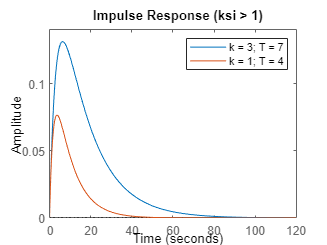


impulse(licz6, mian6)

hold on

impulse(licz7, mian7)

legend('k = 3; T = 7', 'k = 1; T = 4')

title('Impulse Response (ksi > 1)')

hold off

### 2.1 D) Całkujący rzeczywisty

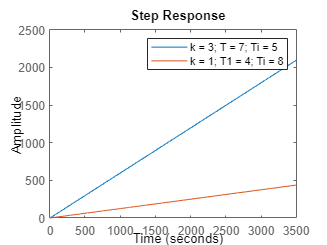

k = 3;
T = 7;
Ti = 5;
k1 = 1;
T1 = 4;
Ti1 = 8;

licz = [0, 0, k];
mian = [T * Ti, Ti, 0];
licz1 = [0, 0, k1];
mian1 = [T1 * Ti1, Ti1, 0];

step(licz, mian)

hold on 

step(licz1, mian1)

legend('k = 3; T = 7; Ti = 5', 'k = 1; T1 = 4; Ti = 8')

hold off

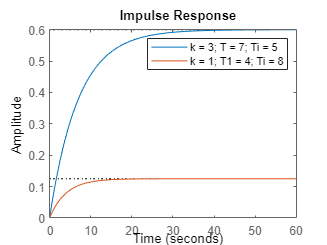


impulse(licz, mian)

hold on

impulse(licz1, mian1)

legend('k = 3; T = 7; Ti = 5', 'k = 1; T1 = 4; Ti = 8')

hold off

### 2.1 E) Różniczkujący rzeczywisty

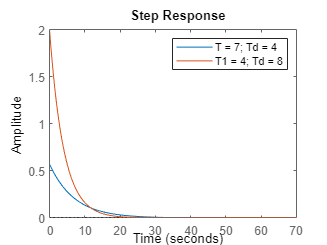

T = 7;
Td = 4;
T1 = 4;
Td1 = 8;

licz = [Td, 0];
mian = [T, 1];
licz1 = [Td1, 0];
mian1 = [T1, 1];

step(licz, mian)

hold on 

step(licz1, mian1)

legend('T = 7; Td = 4', 'T1 = 4; Td = 8')

hold off

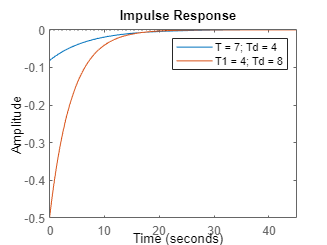


impulse(licz, mian)

hold on

impulse(licz1, mian1)

legend('T = 7; Td = 4', 'T1 = 4; Td = 8')

hold off

### 2.1 F) Inercyjny I rzędu z opóźnieniem

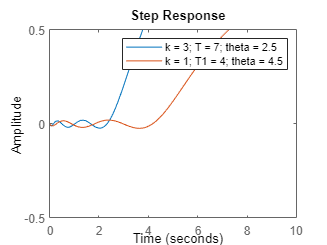

n = 5;

k = 3;
T = 7;
theta = 2.5;
k1 = 1;
T1 = 4;
theta1 = 4.5;

[licz_op, mian_op] = pade(theta, n);
[licz_op1, mian_op1] = pade(theta1, n);

licz_iner = [0,k];
mian_iner = [T,1];
licz_iner1 = [0,k1];
mian_iner1 = [T1,1];

[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
[licz1, mian1] = series(licz_op1, mian_op1, licz_iner1, mian_iner1);

step(licz, mian)

hold on 

step(licz1, mian1)

legend('k = 3; T = 7; theta = 2.5', 'k = 1; T1 = 4; theta = 4.5')

axis([0 10 -0.5 0.5])

hold off

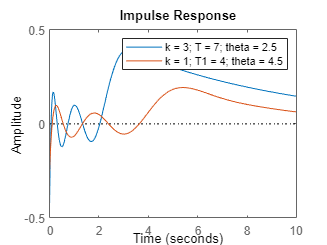


impulse(licz, mian)

hold on

impulse(licz1, mian1)

legend('k = 3; T = 7; theta = 2.5', 'k = 1; T1 = 4; theta = 4.5')

axis([0 10 -0.5 0.5])

hold off

### 2.2 Charaktrystyka częstotliwościowa dla podanych obiektów na wymuszenie:

### 2.2 A) Inercyjny I rzędu

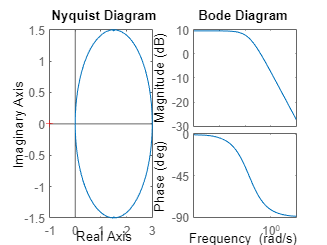

k = 3;
T = 7;

licz = [0, k];
mian = [T, 1];

subplot(1, 2, 2);
bode(licz, mian);

subplot(1, 2, 1);
nyquist(licz, mian);

### 2.2 B) Inercyjny II rzędu

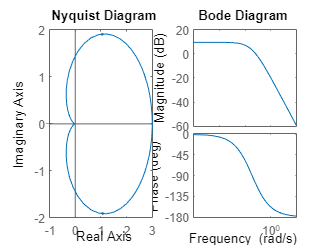

k = 3;
T1 = 7;
T2 = 4;

licz = [0, 0, k];
mian = [T1 * T2, T1 + T2, 1];

subplot(1, 2, 2);
bode(licz, mian);

subplot(1, 2, 1);
nyquist(licz, mian);

### 2.2 C) Inercyjny II rzędu (inna postać)

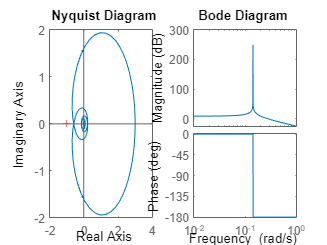

k = 3;
T = 7;
ksi0 = 0;
ksi1 = 0.7;
ksi2 = 1;
ksi3 = 1.3;

licz = [0, 0, k];
mian = [T^2 ,2*ksi0*T ,1];

subplot(1, 2, 2);
bode(licz, mian);

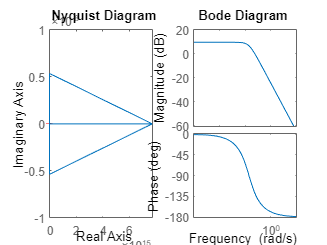


subplot(1, 2, 1);
nyquist(licz, mian);

% Układ oscylacyjny tłumiony

licz2 = [0, 0, k];
mian2 = [T^2 ,2*ksi1*T ,1];

subplot(1, 2, 2);
bode(licz2, mian2);

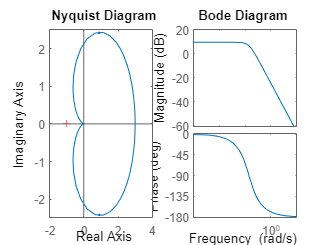


subplot(1, 2, 1);
nyquist(licz2, mian2);

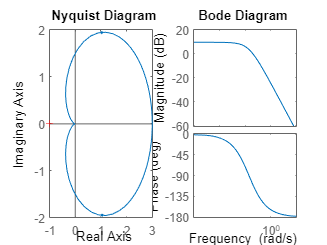


 % Układ aperiodyczny krytyczny 

licz4 = [0, 0, k];
mian4 = [T^2 ,2*ksi2*T ,1];

subplot(1, 2, 2);
bode(licz4, mian4);

subplot(1, 2, 1);
nyquist(licz4, mian4);

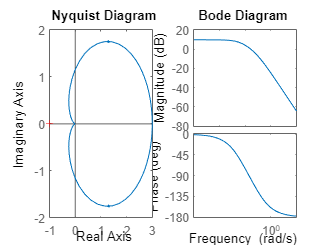


% Układ aperiodyczny

licz6 = [0, 0, k];
mian6 = [T^2 ,2*ksi3*T ,1];

subplot(1, 2, 2);
bode(licz6, mian6);

subplot(1, 2, 1);
nyquist(licz6, mian6);

### 2.2 D) Całkujący rzeczywisty

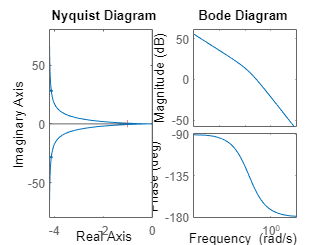

k = 3;
T = 7;
Ti = 5;

licz = [0, 0, k];
mian = [T * Ti, Ti, 0];

subplot(1, 2, 2);
bode(licz, mian);

subplot(1, 2, 1);
nyquist(licz, mian);

### 2.2 E) Różniczkujący rzeczywisty

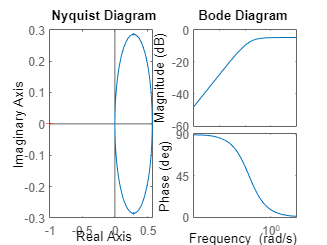

T = 7;
Td = 4;

licz = [Td, 0];
mian = [T, 1];

subplot(1, 2, 2);
bode(licz, mian);

subplot(1, 2, 1);
nyquist(licz, mian);

### 2.2 F) Inercyjny I rzędu z opóźnieniem

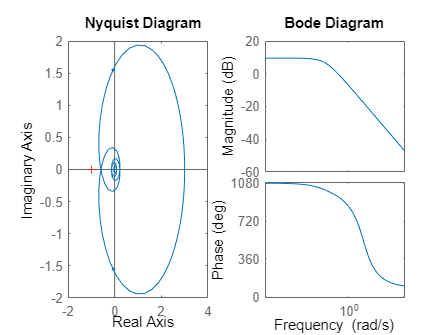

n = 5;

k = 3;
T = 7;
theta = 2.5;

[licz_op, mian_op] = pade(theta, n);

licz_iner = [0,k];
mian_iner = [T,1];

[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);

subplot(1, 2, 2);
bode(licz, mian);

subplot(1, 2, 1)
nyquist(licz, mian);